format long e
f=@(x) x.*exp(x)-2;
r = fzero(f,1);
fprintf("Root of function= %.10f",r);

Root of function= 0.8526055020


x=1;
%Using newtons method
df=@(x) exp(x)*(x+1);
for k=1:6
    x(k+1)=x(k) - f(x(k))/df(x(k));
end
fprintf("Approximation after iteration %d: %.10f\n", k, x(k+1));

Approximation after iteration 6: 0.8526055020


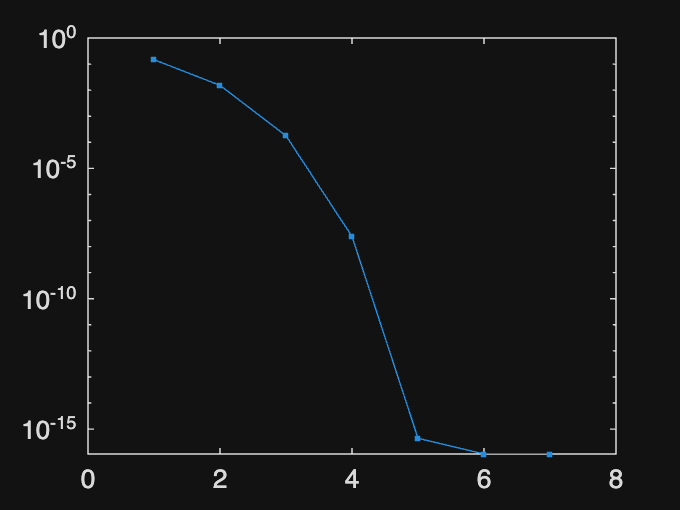


error= x-r;

semilogy(abs(error),'.-');

xlabel('Iteration Number');
ylabel('Absolute Error');
title('Convergence of Newton''s Method');
grid on;